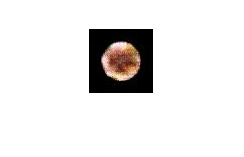

load("Classify_model_aug.mat")

imds = imageDatastore("gen_images",LabelSource="foldernames",IncludeSubfolders=true);

imshow(readimage(imds,1))

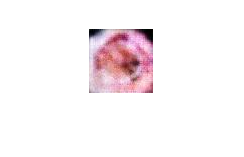

imshow(readimage(imds,2))

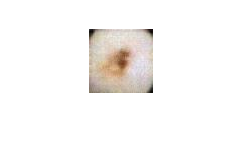

imshow(readimage(imds,3))


testds = augmentedImageDatastore([227 227],imds,"ColorPreprocessing","gray2rgb");

preds = classify(Classify_model_aug,testds);

Compare with reality

truetest = imds.Labels;
nnz(preds == truetest)/numel(preds)

ans = 0.7660

View confusion matrix

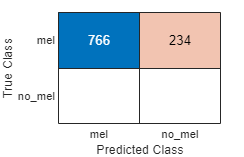

confusionchart(truetest,preds);

View first incorrect classification (if there is one)

idx = find(preds~=truetest)

idx =      3
    10
    19
    28
    33
    37
    38
    41
    44
    49


if ~isempty(idx)
    imshow(readimage(testImgs,idx(1)))
    title(truetest(idx(1)))
end

Unrecognized function or variable 'testImgs'.